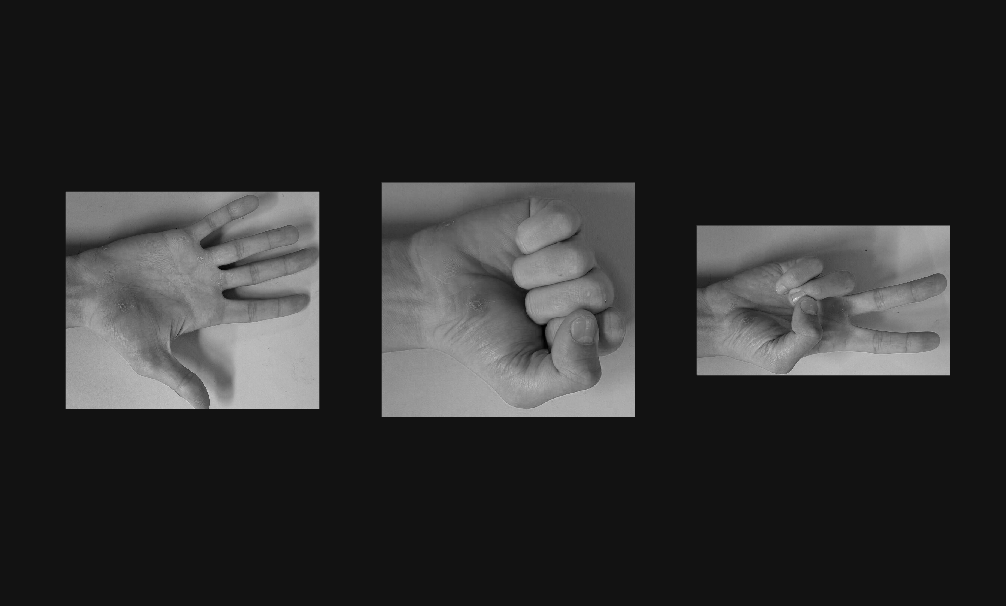

clc;
clear;
Paper_Template = imread('Paper_Template.jpg');
Paper_Template = Paper_Template(600:1500,1000:2050);
Rock_Template = imread('Rock_Template.jpg');
Rock_Template = Rock_Template(600:1225,1000:1675);
Scissors_Template = imread('Scissors_Template.jpg');
Scissors_Template = Scissors_Template(600:1250,1000:2100);



tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile;
imshow(Paper_Template)
nexttile;
imshow(Rock_Template)
nexttile;
imshow(Scissors_Template)

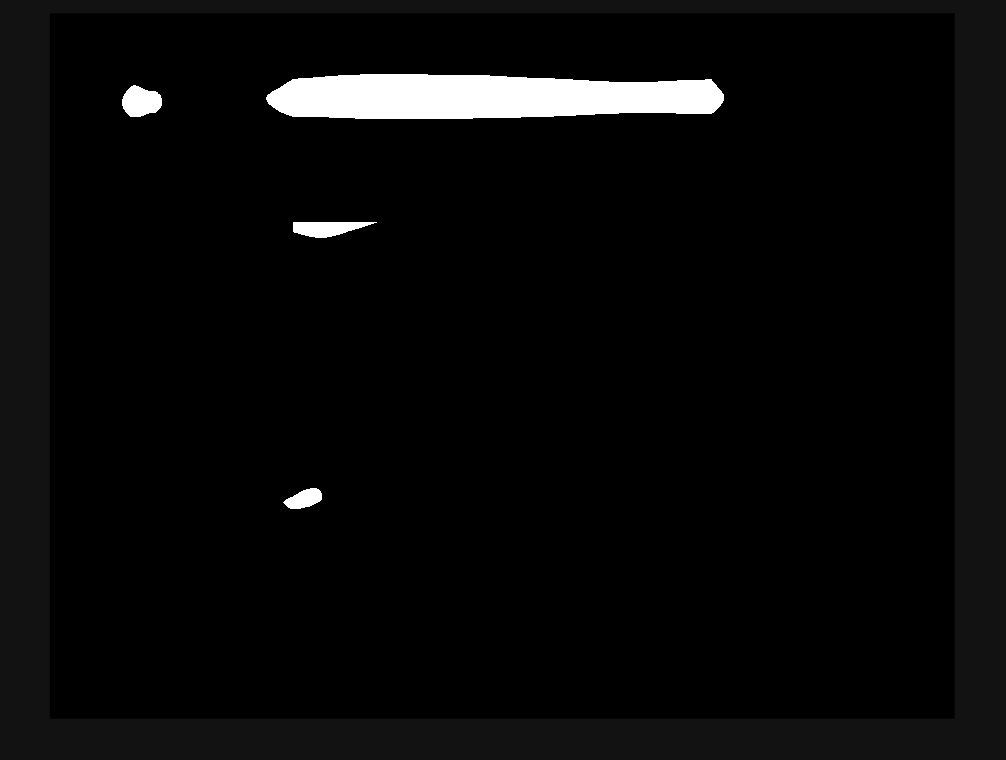

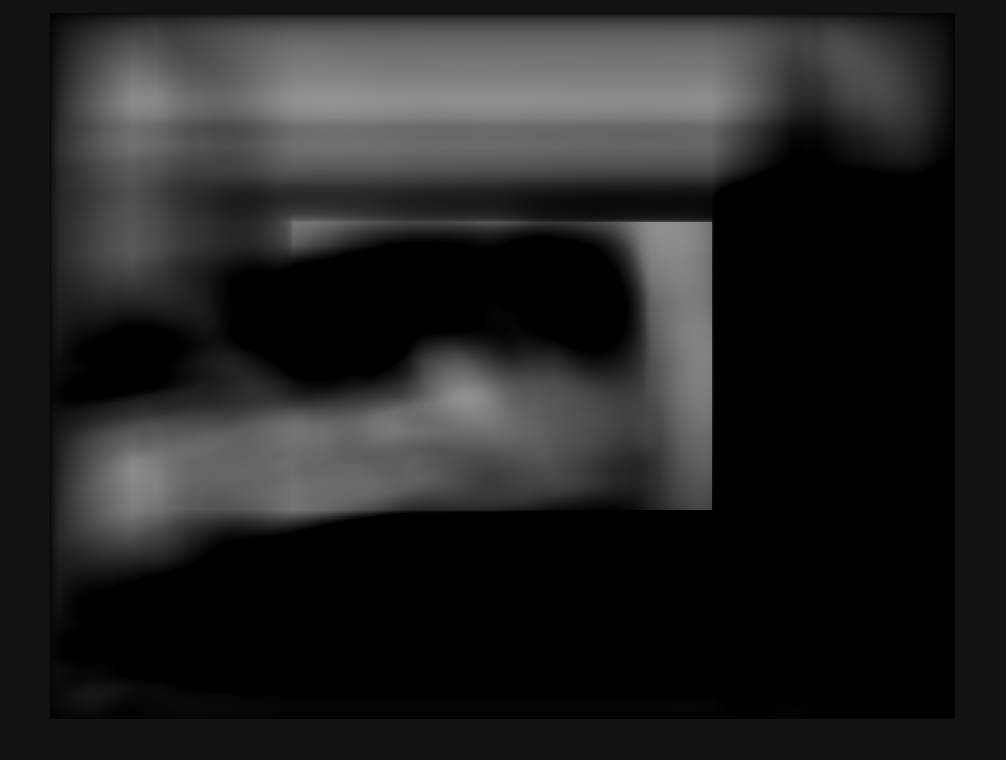

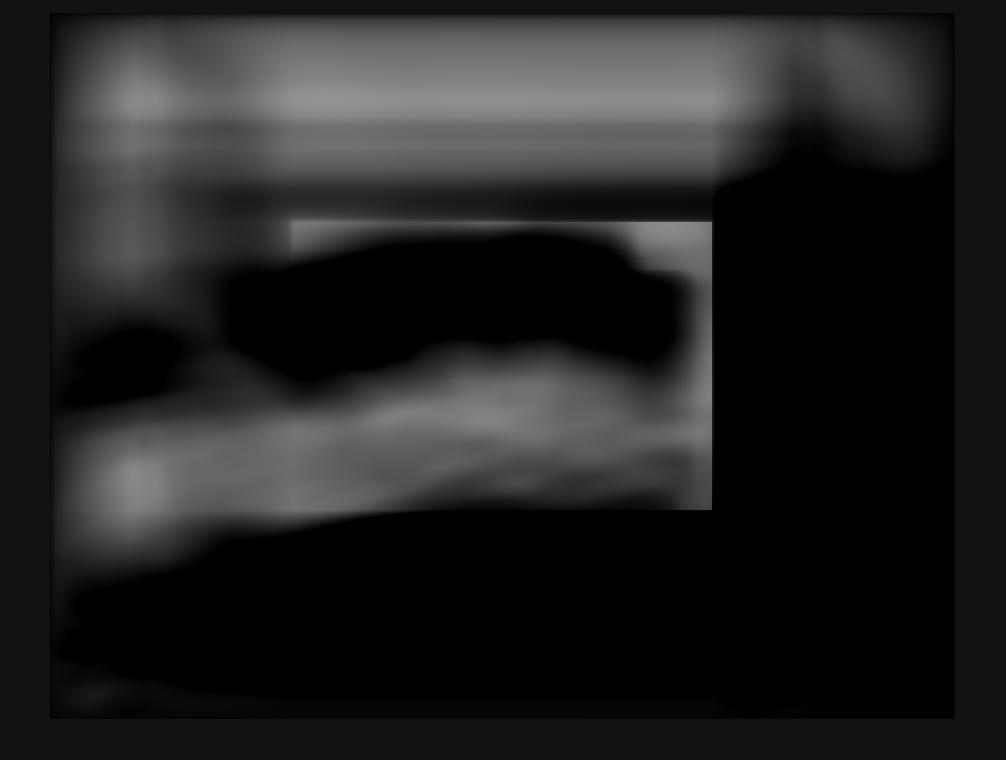

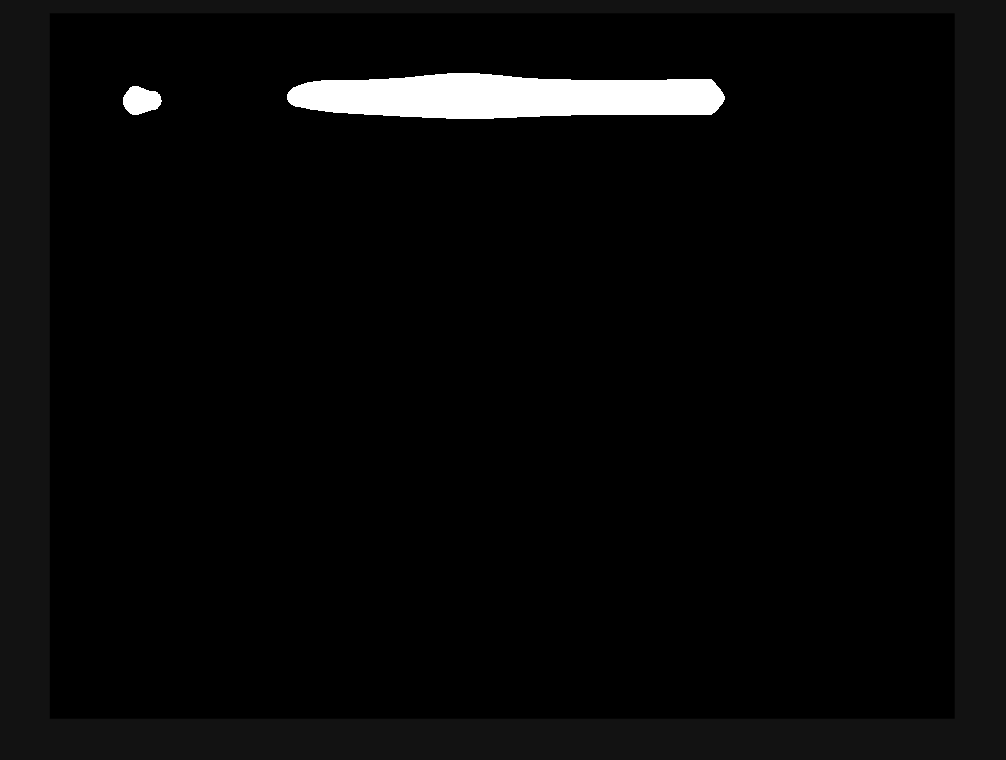

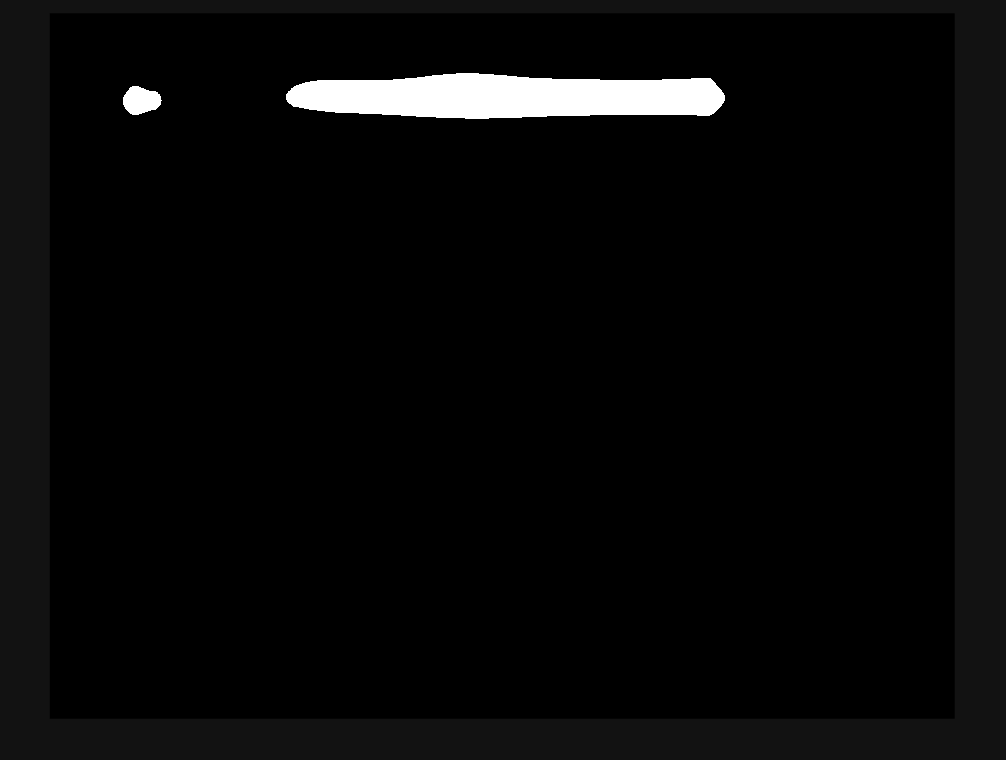

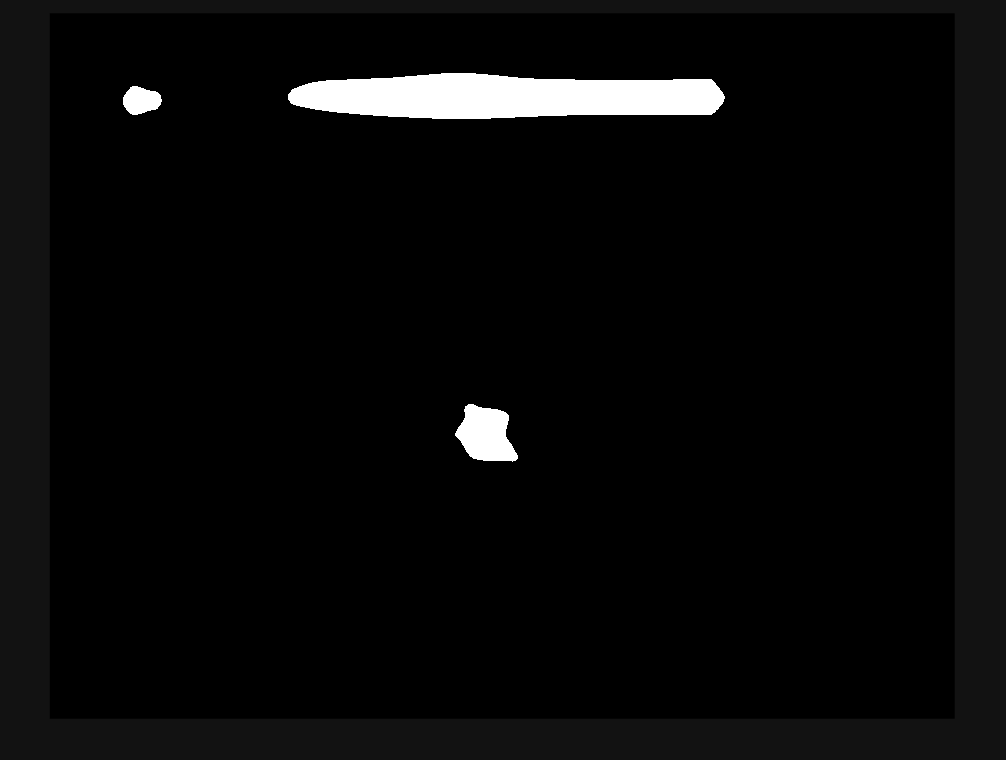

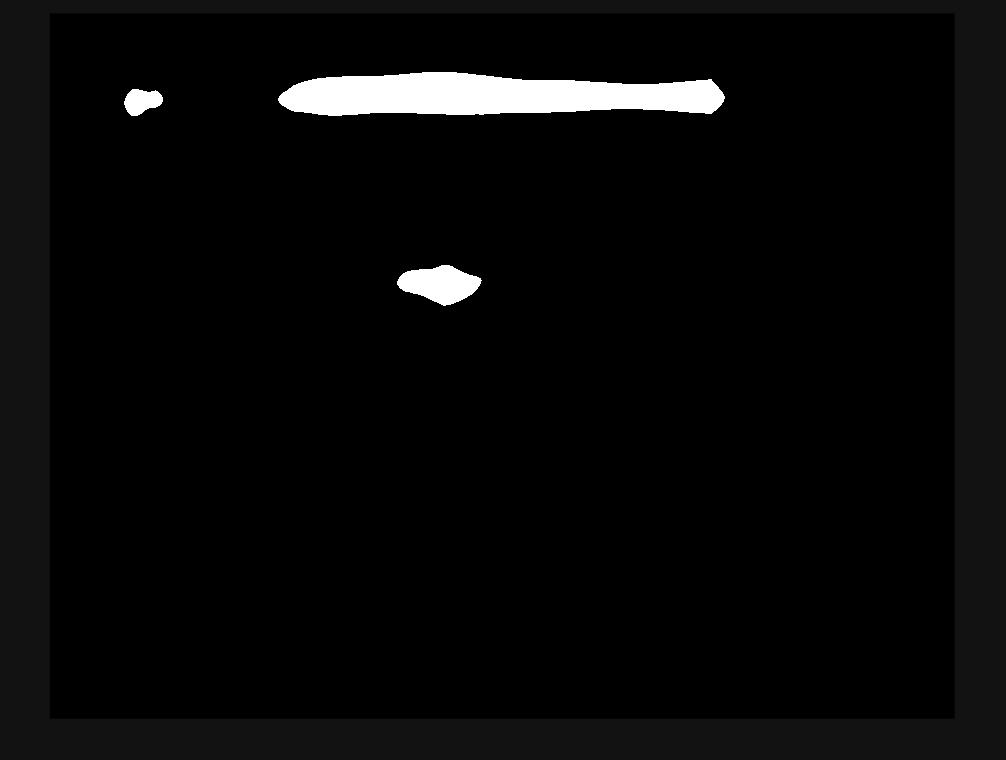

theFiles = dir(fullfile('Hand_Images', '*.jpg'));
for k = 1:length(theFiles)
    figure(k+1)
    baseFileName = theFiles(k).name;
    fullFileName = fullfile(theFiles(k).folder, baseFileName);
    image = imread(fullFileName);
    gray_image  = im2gray(image);
    paper = normxcorr2(Paper_Template,gray_image);
    rock = normxcorr2(Rock_Template,gray_image);
    scissors = normxcorr2(Scissors_Template,gray_image);
    imshow(paper>.5)
end